disp("Part B (1)")

Part B (1)


A = [0, 0, 1, 0; 
     0, 0, 0, 1; 
     -0.9, 0.9, -0.09, 0.09; 
     0.1, -0.1, 0.01, -0.01]; 
disp(A)

         0         0    1.0000         0
         0         0         0    1.0000
   -0.9000    0.9000   -0.0900    0.0900
    0.1000   -0.1000    0.0100   -0.0100




% Calculate the eigenvalues and eigenvectors of matrix A
[eigenVectors, eigenValues] = eig(A);

disp(diag(eigenValues)) 

  -0.0500 + 0.9987i
  -0.0500 - 0.9987i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i



disp("Part B (2)")

Part B (2)


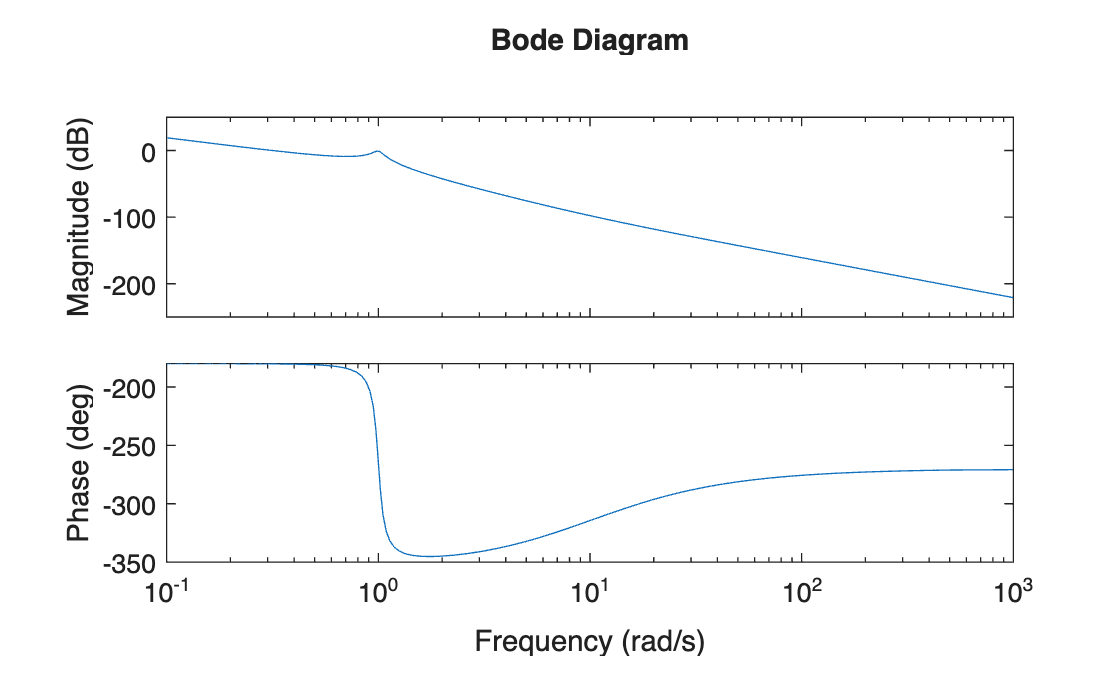

A = [0, 0, 1, 0; 
     0, 0, 0, 1; 
     -0.9, 0.9, -0.09, 0.09; 
     0.1, -0.1, 0.01, -0.01]; 

B = [0; 0; 0.9; 0]; 

C = [0, 1, 0, 0]; 

D = 0; 

sys = ss(A, B, C, D); 

bode(sys)


pole(sys)

ans =   -0.0500 + 0.9987i
  -0.0500 - 0.9987i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i



zero(sys)

ans = -10.0000

disp("Part C")

Part C


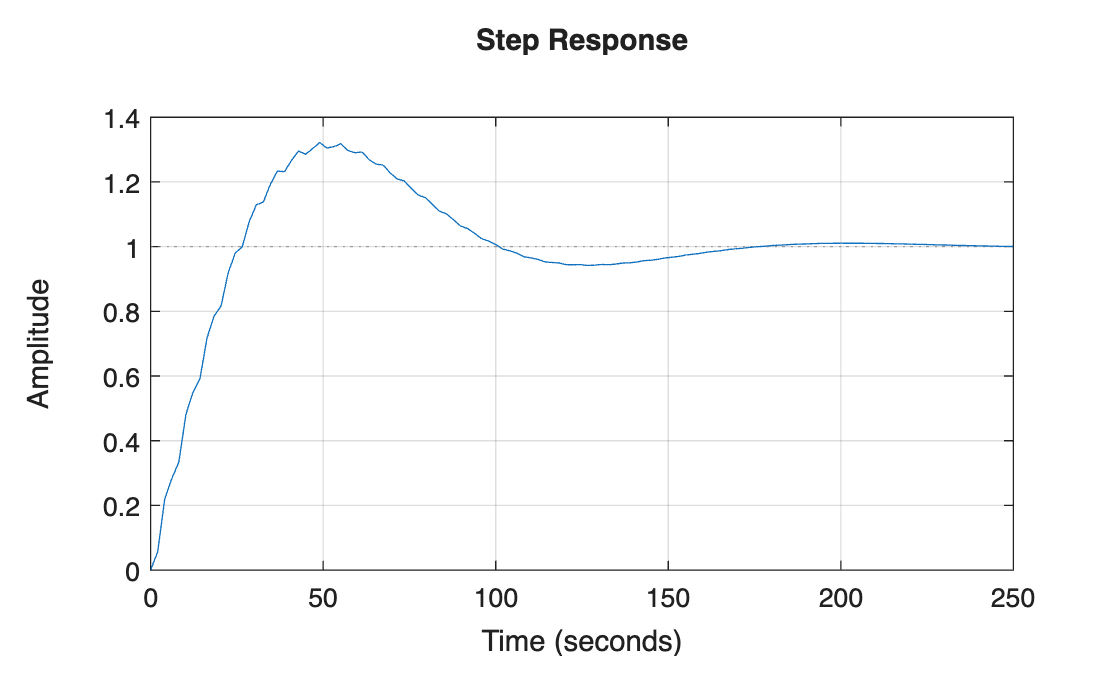

Kp = 0.025;
Kd = 0.5;

C_pd = tf([Kd Kp],[1]);

sys_cl = feedback(C_pd*sys,1);

step(sys_cl)
grid on


info = stepinfo(sys_cl, 'SettlingTimeThreshold', 0.02);
ss_error = abs(1 - dcgain(sys_cl));

fprintf('Rise time: %.3f s\n', info.RiseTime);

Rise time: 19.502 s


fprintf('Settling time: %.3f s\n', info.SettlingTime);

Settling time: 159.718 s


fprintf('Percent overshoot: %.2f %%\n', info.Overshoot);

Percent overshoot: 32.18 %


fprintf('Steady-state error: %.3f rad\n', ss_error);

Steady-state error: 0.000 rad


disp("Part D (1) ")

Part D (1) 


desired_poles = [-2, -1, -1+1i, -1-1i];

K = place(A, B, desired_poles);

disp(K); 

    8.9333   35.5111    5.4444  101.2222




Acl = A - B*K;
eigAcl = eig(Acl); 
disp(eigAcl)

  -2.0000 + 0.0000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i
  -1.0000 + 0.0000i



disp("Part D (2)")

Part D (2)



Kr = -1 / (C * ((A - B*K) \ B))

Kr = 44.4444

disp("Part D (3)")

Part D (3)


Bcl = B * Kr

Bcl =          0
         0
   40.0000
         0


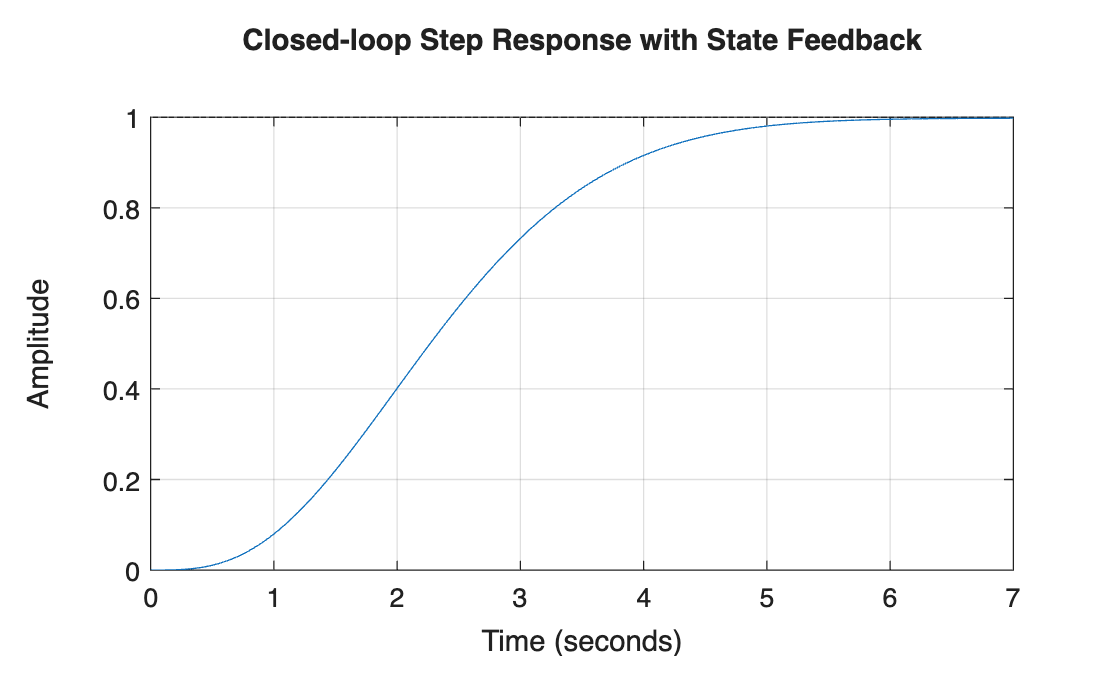


Acl = A - B*K;
Bcl = B*Kr;

sys_fb = ss(Acl, Bcl, C, 0);

step(sys_fb)
grid on
title('Closed-loop Step Response with State Feedback')


info = stepinfo(sys_fb, 'SettlingTimeThreshold', 0.02);
ss_error = abs(1 - dcgain(sys_fb));

fprintf('Rise time: %.3f s\n', info.RiseTime);

Rise time: 2.782 s


fprintf('Settling time: %.3f s\n', info.SettlingTime);

Settling time: 4.984 s


fprintf('Percent overshoot: %.2f %%\n', info.Overshoot);

Percent overshoot: 0.00 %


fprintf('Steady-state error: %.3f rad\n', ss_error);

Steady-state error: 0.000 rad
